# Understanding the Hansen-Woodyard End Fire Array

An analysis of the Hansen-Woodyard End-Fire Array in comparison to an ordinary array.

Kristtiya Guerra

#### Parameters:

N = 2;                     % Number of elements in array
f = 2*10^9;                 % Frequency
c = 3*10^8;                 % Speed of Light
lambda = c/f;               % Wavelenght
k = 2*pi/lambda;            % Wave Number
theta = 0:.00001:2*pi;      % Angle (theta)

#### Antenna Models

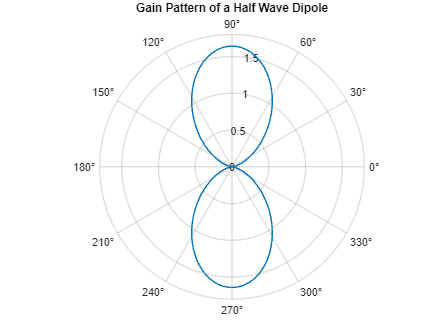

%G = (1.67.*sin(theta).^3)
G = 1.64.*(cos(cos(theta).*pi./2).^2)./(sin(theta).^2); %Half-Wave Dipole
%G = (3./2).*sin(theta).^2;                             % 

polarplot(theta, G)
hold on
title('Gain Pattern of a Half Wave Dipole');
drawnow
hold off

## Antenna Arrays

### Array Factor

The array factor is a formula that is used to represent a N-element array. The model uses the assumption that each element in the array are identical nodes. 


$$AF_{N} =\frac{1}{N}\frac{sin(\psi N /2)}{sin(\frac{\psi}{2})}$$


The product of the array factor with an antenna model of the designer's choice (for example, the gain of a dipole) is an N-element array.

#### Ordinary End-Fire Arrays

An ordinary end-fire array is characterized by an N-element array of equally spaced antennas. Each antenna are identical and of equally magnitude. The ordinary end-fire array can only be modified by the number of elements in the array and the distance between each element. The spacing determines if the antenna will point in both directions, or in only one direction.

N = 10;                                                % Number of elements in the array
d = [lambda/2;lambda/4;lambda/6;lambda;4*lambda];      % Distance between each antenna element
k = 2.*pi./lambda;                                     % Wave number

The phase shift for an ordinary end fire array is equal to $\beta = -kd$ for $\theta = 0$ and $\beta = kd$° for $\theta = 180$°. It is not influenced by the number of elements.

beta = k.*d;                                           % Phase Shift
psi = k*d.*cos(theta) + beta;                          
AF_n = abs((sin(psi.*N./2) ./ sin(.5.*psi) )./N);      % Array Factor

You can visibly see in this plot how the distance between antenna elements affects the overall pattern of the array factor. For the antenna to have major lobes pointing at both ends, the space between the elements should be $d = \lambda/2, \lambda, n\lambda$ where $n = 1,2,3,...$. 

However, the further the distance between the elements, the more high intensity lobes will appear.

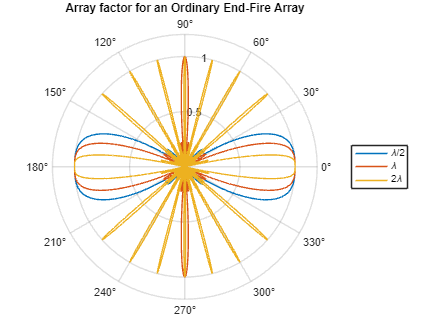

polarplot(theta,AF_n(1,:));
hold on
polarplot(theta,AF_n(4,:));
polarplot(theta,AF_n(5,:));
title('Array factor for an Ordinary End-Fire Array');
legend('\lambda/2','\lambda','2\lambda');
hold off

In order for the antenna to point in only one direction, the distance between elements needs to be decreased.

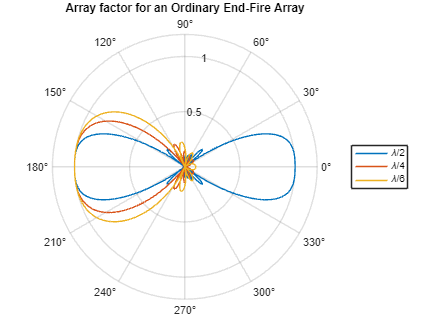

polarplot(theta,AF_n(1,:));
hold on
polarplot(theta,AF_n(2,:));
polarplot(theta,AF_n(3,:));
title('Array factor for an Ordinary End-Fire Array');
legend('\lambda/2','\lambda/4','\lambda/6');
hold off

#### Hanson-Woodyard End-Fire Array

The Hansen-Woodyard Array is a modified form of the Ordinary End-fire array. It features a progressive phase shift that is influenced by the number of elements.

$\beta = -(kd + \frac{2.92}{N})$ for $\theta = 0$°

$\beta = +(kd + \frac{2.92}{N})$ for $\theta = 180$°

The distance between elements is also influenced by the number of elements - the smaller amount of elements, the closer together. The higher number, the closer to $d \approx \lambda/4$.


$$d = (\frac{N-1}{N})\frac{\lambda}{4}$$


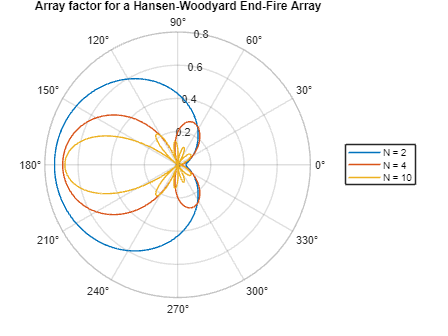

N = [2;4;10];
d = ((N-1)./N).*(lambda./4);                  % Distance between each antenna element
beta = k.*d + 2.94./N;                        % Phase Shift
psi = k*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi).*N;
AF_N = abs(AF_num./AF_den);

polarplot(theta,AF_N);
hold on
title('Array factor for a Hansen-Woodyard End-Fire Array')
legend('N = 2','N = 4','N = 10');
hold off

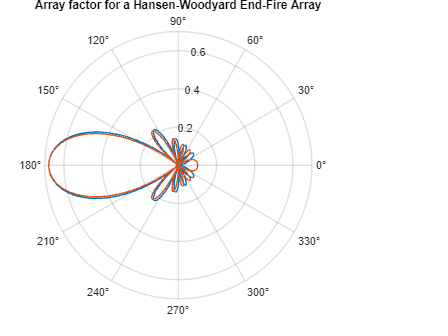

N = 10;
d = [((N-1)./N).*(lambda./4);lambda/4];                  % Distance between each antenna element
beta = k.*d + 2.94./N;                        % Phase Shift
psi = k*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi).*N;
AF_N = abs(AF_num./AF_den);

polarplot(theta,AF_N);
hold on
title('Array factor for a Hansen-Woodyard End-Fire Array')
hold off

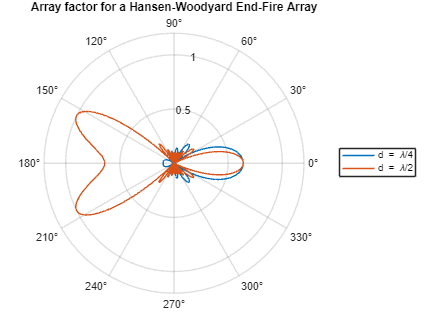

N = 10;
d = [lambda./4;lambda/2];                  % Distance between each antenna element
beta = -(k.*d + pi./N);                        % Phase Shift
psi = k*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi).*N;
AF_N = abs(AF_num./AF_den);

polarplot(theta,AF_N);
hold on
title('Array factor for a Hansen-Woodyard End-Fire Array')
legend('d = \lambda/4','d = \lambda/2');
hold off

Effect of distance between each element and the back lobe

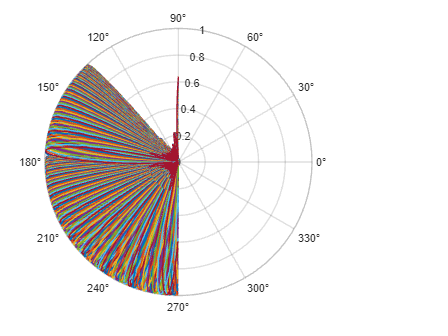

theta = pi/2:lambda/10:3*pi/2;      % Angle (theta)
N = 10;
a = size(theta,2);
% d = [2*lambda;lambda;lambda/2;lambda/4;lambda/6];                  % Distance between each antenna element
d = 0:2*lambda/a:2*lambda;
d = d(1:end-1).';
beta = -(k.*d + pi./N);                        % Phase Shift
psi = k.*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi);
AF_N = abs(AF_num./AF_den)./N;
peak = max(AF_N);

polarplot(theta,AF_N);

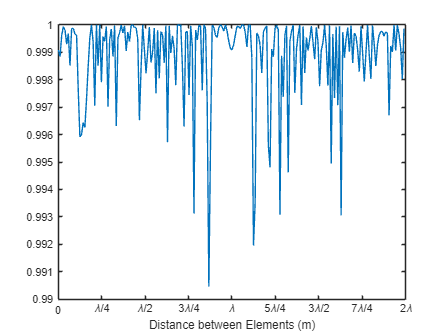



plot(d,peak)
hold on
xlabel('Distance between Elements (m)')
set(gca,'Xtick',0:lambda/4:2*lambda,'XTickLabel',{'0','\lambda/4','\lambda/2','3\lambda/4','\lambda','5\lambda/4','3\lambda/2','7\lambda/4','2\lambda'});
hold off

theta = pi/2:lambda/10:3*2*pi;      % Angle (theta)
N = 10;
a = size(theta,2);
G = 1.64.*(cos(cos(theta+pi/2).*pi./2).^2)./(sin(theta+pi/2).^2); %Half-Wave Dipole

% d = [2*lambda;lambda;lambda/2;lambda/4;lambda/6];                  % Distance between each antenna element
d = 0:2*lambda/a:2*lambda;
d = d(1:end-1).';
beta = -(k.*d + pi./N);                        % Phase Shift
psi = k.*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi);
AF_N = abs(AF_num./AF_den)./N;
Pattern = G.*AF_N;
peak = max(Pattern);


Interactive plot of Radiation Pattern 

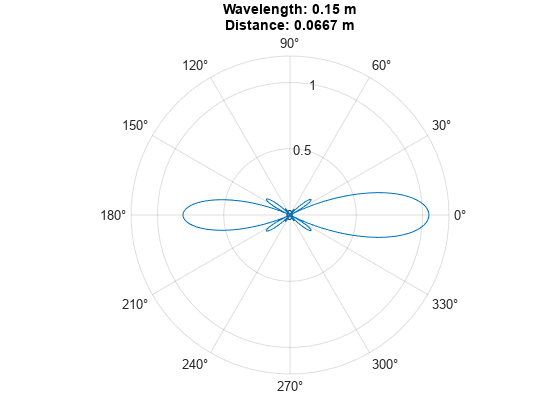

for i=1:size(theta,2)
    polarplot(theta,Pattern(i,:))
    	h = title({sprintf('Wavelength: %.2f m',lambda);sprintf('Distance: %.4f m',d(i))}); % title is 13 chars in both cases        
    drawnow
end